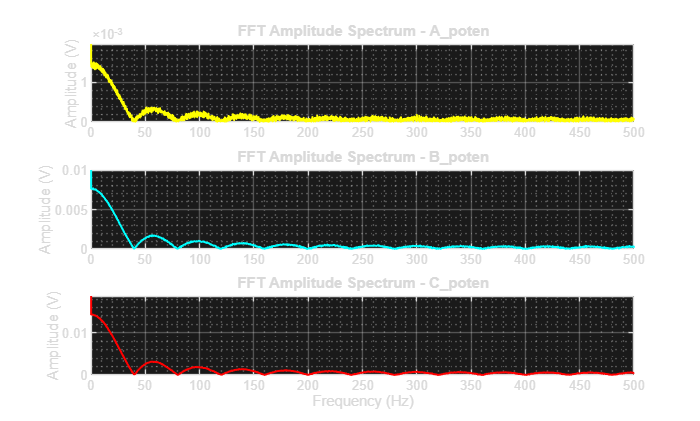

% --- 1. ดึงข้อมูลแรงดัน และแปลงชนิดข้อมูลเป็น double ---
v1 = double(squeeze(data_static.A_poten.Data)); v1 = v1(:);
v2 = double(squeeze(data_static.B_poten.Data)); v2 = v2(:);
v3 = double(squeeze(data_static.C_poten.Data)); v3 = v3(:);

% --- 2. ตั้งค่าพารามิเตอร์ระบบ ---
Fs = 1000;           % Sampling Frequency (1000 Hz)
L = length(v1);      % จำนวนจุดข้อมูลทั้งหมด

% --- 3. คำนวณ FFT แบบ Single-Sided Amplitude Spectrum ---
Y1 = fft(v1); P1_two = abs(Y1 / L); P1_one = P1_two(1 : floor(L/2) + 1); P1_one(2:end-1) = 2 * P1_one(2:end-1);
Y2 = fft(v2); P2_two = abs(Y2 / L); P2_one = P2_two(1 : floor(L/2) + 1); P2_one(2:end-1) = 2 * P2_one(2:end-1);
Y3 = fft(v3); P3_two = abs(Y3 / L); P3_one = P3_two(1 : floor(L/2) + 1); P3_one(2:end-1) = 2 * P3_one(2:end-1);

f = (0 : floor(L/2)) * (Fs / L);

% --- 4. พล็อตกราฟซูมระดับ Noise (มองข้าม DC Peak ที่ 0 Hz) ---
figure('Color', 'w', 'Name', 'FFT Amplitude Spectrum (Zoomed View)');

% Subplot 1: A_poten
subplot(3, 1, 1);
plot(f, P1_one, 'y-', 'LineWidth', 1.2);
ax1 = gca; ax1.Color = [0.1 0.1 0.1]; grid on; grid minor;
title('FFT Amplitude Spectrum - A\_poten');
ylabel('Amplitude (V)');
xlim([0 500]);                      % ปรับเป็น [0 50] ได้หากต้องการซูมย่านความถี่ต่ำ
ylim([0, max(P1_one(2:end))*1.3]);  % ซูมแกน Y โดยคิดเฉพาะค่าความถี่ > 0 Hz

% Subplot 2: B_poten
subplot(3, 1, 2);
plot(f, P2_one, 'c-', 'LineWidth', 1.2);
ax2 = gca; ax2.Color = [0.1 0.1 0.1]; grid on; grid minor;
title('FFT Amplitude Spectrum - B\_poten');
ylabel('Amplitude (V)');
xlim([0 500]);
ylim([0, max(P2_one(2:end))*1.3]);

% Subplot 3: C_poten
subplot(3, 1, 3);
plot(f, P3_one, 'r-', 'LineWidth', 1.2);
ax3 = gca; ax3.Color = [0.1 0.1 0.1]; grid on; grid minor;
title('FFT Amplitude Spectrum - C\_poten');
xlabel('Frequency (Hz)');
ylabel('Amplitude (V)');
xlim([0 500]);
ylim([0, max(P3_one(2:end))*1.3]);